# polyfitOrtho

fits a polynomial using orthogonal bais in a least squares sense

## Syntax

## Inputs

- **x_mu** - vector of x points to fit. m = numel(x_mu) by definition. 

- **f_mu** - vector of y points to fit. f_mu must have m elements. 

- **k** - polynomial order.

## Outputs

- **coefficientsAndResults** - A structure containing the **coefficients**, **alphas**, **betas**, and **variances**'. The structure always has k+1 rows. **coefficientsAndResults **has the following fields:

- **s** - is the cofficients of each polynomial.

- **alpha** - The 1st coefficient it the orthogonality procedure. 

- **beta** - The 2nd coefficient in the orthogonality procedure. 

- **variance** - The variance of the residuals for each polynomial fit. 

## Description

This function fits a polynomial of order $k$ to $x_{\mu } ,f_{\mu \;}$. An orthogonal basis is used published by Forsythe [1]. Unlike polyfit, fitting 100th degree or greater polynomial is no problem. 

This functions fits a polynomial of the form:

            
$$y_k \left(x\right)=s_0 \;p_0 \left(x\right)+s_1 \;p_1 \left(x\right)+\ldotp \ldotp \ldotp +s_k p_k \left(x\right)$$


where

- $p_i \left(x\right)$ is a polynomial of order $i$. By definition, $p_i$ is orthogonal to $p_j$ as long as $i\not= j$ on the inner product,$\sum_{\mu } p_i \left(x_{\mu \;} \right)\;p_j \left(x_{\mu \;} \right)$. 

- $s_i$ is the coefficient of $p_i$. 

- $y_k \left(x\right)$ is a polynomial of order $k$ constructed from polynomials that are orthogonal on the inner product $\sum_{\mu } p_i \left(x_{\mu \;} \right)\;p_j \left(x_{\mu \;} \right)$.

The orthogonal polynomials, $p_i$, are generated using the following definition:


$$\begin{array}{l}
p_0 \left(x\right)=1\\
p_1 \left(x\right)=x\;p_0 \left(x\right)-\alpha {\;}_1 \;p_0 \left(x\right)\\
p_2 \left(x\right)=x\;p_1 \left(x\right)-\alpha {\;}_2 \;p_1 \left(x\right)-\beta {\;}_1 \;p_0 \left(x\right)\\
\ldotp \ldotp \ldotp \;\;\;\;\;\;\;\;\;\;\;\ldotp \ldotp \ldotp \\
p_{i+1} \left(x\right)=x*p_i \left(x\right)-\alpha {\;}_{i+1} \;p_i \left(x\right)-\beta {\;}_i \;p_{i-1} \left(x\right)
\end{array}$$


$\alpha \;$ and $\beta \;$are chosen to make the orthogonality relations hold. See Forsythe, [1] for derivation. The formulas for the $\alpha$'s and $\beta$'s are


$$\begin{array}{l}
\alpha {\;}_{i+1} =\frac{\sum_{\mu =1}^m {x_{\mu \;} \left(p_i \left(x_{\mu } \right)\right)}^2 }{\sum_{\mu =1}^m {\left(p_i \left(x_{\mu } \right)\right)}^2 }\\
\beta {\;}_i =\frac{\sum_{\mu =1}^m x_{\mu } \;p_i \left(x_{\mu } \right)\;p_{i-1} \left(x_{\mu \;} \right)}{\sum_{\mu =1}^m {\left(p_{i-1} \left(x_{\mu } \right)\right)}^2 }
\end{array}$$


Note that more involved, less intuitive formulas are used in the code. These formulas can be found in Forsythe, [1].

The beauty of this formulation is that the least squares problem is diagonal:


$$\begin{array}{l}
w_{\textrm{ii}} =\sum_{\mu =1}^m {\left(p_i \left(x_{\mu \;} \right)\right)}^2 \\
\omega_i =\sum_{\mu =1}^m \;f_{\mu \;} p_i \left(x_{\mu \;} \right)\\
\left\lbrack \begin{array}{cccc}
w_{00} \;s_0  & 0 & 0 & 0\\
0 & w_{11} \;s_1  & 0 & 0\\
0 & 0 & \ddots  & 0\\
0 & 0 & 0 & w_{\textrm{kk}} \;s_k 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\omega {\;}_0 \\
\omega {\;}_1 \\
\omega {\;}_2 \\
\omega {\;}_3 
\end{array}\right\rbrack 
\end{array}$$


Some other important properties:

- The algorithm does not require forming the A matrix in the least squares problem $\textrm{Ax}=b$. 

- The algorithm finds each coefficient $s_i$, in order from $0$ to $k$. This has the property that you get all polynomial fits from $0$ to $k$ by requesting *k*th polynomial fit. Use $0$ to $k_2$ rows where $k_2 <k$.

- The variance of the residuals is calculated for each $i$ from $0$ to $k$ by an update formula.

- The least square problem is better formed than Vandermonde matrices (i.e. x.^(0:k), aka monomial basis). This allows fitting of much higher order polynomials. The monomial basis is exponentially ill-conditioned. The basis used in this function is much better conditioned.

- The algorithm time complexity is O(k*m). This is better than the QR decompositions's O(2*m*k^2). 

## Example

Fit a 186th degree polynomial to the Runge function on 500 Chebyshev points. The Chebyshev points are chosen because high degree interpolating polynomials are known to converge to the Runge function.

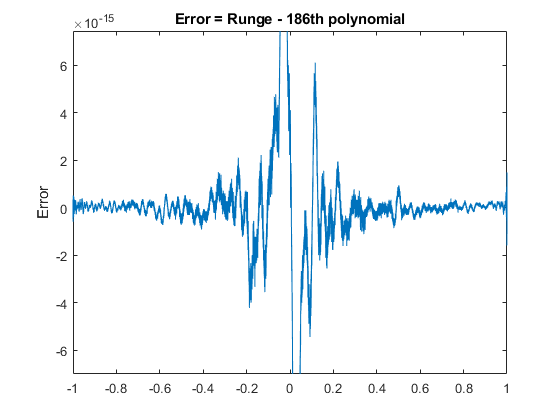

runge = @(x) 1./(1+25*x.^2);
theta = linspace(pi,0,500);
x = cos(theta); % Chebyshev points
y = runge(x);
k = 186;
coefficientsAndResults = polyfitOrtho(x,y,k);
figure;
fplot(@(x) runge(x)-polyvalOrtho(x,coefficientsAndResults),[-1 1])
ylabel('Error')
title(sprintf('Error = runge(x) - %dth polynomial',k))

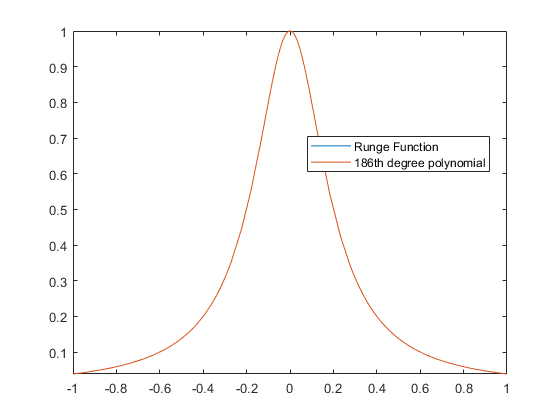

figure;
fplot(@(x) runge(x),[-1 1])
hold all;
fplot(@(x) polyvalOrtho(x,coefficientsAndResults),[-1 1])
legend(["Runge Function", sprintf("%dth degree polynomial",k)],'location','best')

## References

The algorithm and nomenclature comes from Forsythe 1957. 

[1] Forsythe, George E. "Generation and use of orthogonal polynomials for data-fitting with a digital computer." Journal of the Society for Industrial and Applied Mathematics 5.2 (1957): 74-88.

See also polyvalOrtho, polyfit, polyval.